clc;
syms x y;

a = 1;

u = a .* (x^2 - y^2);
v = - 2 .* x .* y;

exist_stream = diff(u, x) + diff(v, y);
exist_velocity_potentian = diff(v, x) - diff(u, y);

if (simplify(exist_stream) == 0)
    disp('Stream function exists')
else
    disp('Stream function does not exists')
end

Stream function exists



if (simplify(exist_velocity_potentian) == 0)
    disp('Velocity potential exists')
else
    disp('Velocity potential  does not exists')
end

Velocity potential exists



psi = int(u, y);
psi = psi + int(diff(psi, x) + v, x)

$$psi = x^{2}\,y-\frac{y^{3}}{3}$$


phi = int(u, x);
phi = phi + int(diff(phi, y) - v, y)

$$phi = \frac{x^{3}}{3}-x\,y^{2}$$

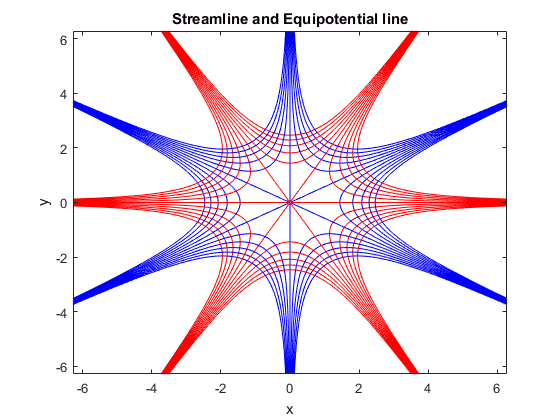


for i = -5:5
    
    hold on
    
    f1 = ezplot(psi == i);
    set(f1, 'color', 'r', 'Linestyle', '--')
    
    f2 = ezplot(phi == i);
    set(f2, 'color', 'b', 'Linestyle', '-.')
    
    title('Streamline and Equipotential line')
    
end